## License

Please cite the following publication when using or adapting this software or substantial portion thereof for work resulting a publication:

Rose O., Johnson J.K., Wang B. and Ponce C.R.; As simple as possible, but not simpler: features of the neural code for object recognition; JOURNAL TBA

(also see the CITATION file)

MIT License

Copyright (c) 2021 PonceLab

Permission is hereby granted, free of charge, to any person obtaining a copy of this software and associated documentation files (the "Software"), to deal in the Software without restriction, including without limitation the rights to use, copy, modify, merge, publish, distribute, sublicense, and/or sell copies of the Software, and to permit persons to whom the Software is furnished to do so, subject to the following conditions:

The above copyright notice and this permission notice shall be included in all copies or substantial portions of the Software.

THE SOFTWARE IS PROVIDED "AS IS", WITHOUT WARRANTY OF ANY KIND, EXPRESS OR IMPLIED, INCLUDING BUT NOT LIMITED TO THE WARRANTIES OF MERCHANTABILITY, FITNESS FOR A PARTICULAR PURPOSE AND NONINFRINGEMENT. IN NO EVENT SHALL THE AUTHORS OR COPYRIGHT HOLDERS BE LIABLE FOR ANY CLAIM, DAMAGES OR OTHER LIABILITY, WHETHER IN AN ACTION OF CONTRACT, TORT OR OTHERWISE, ARISING FROM, OUT OF OR IN CONNECTION WITH THE SOFTWARE OR THE USE OR OTHER DEALINGS IN THE SOFTWARE.

% add the necessary files to the path (this should be all that is required)
addpath(genpath(pwd))
addpath(genpath(fullfile(fileparts(pwd),'data')))

imgdir = ".\data\cloud_vision_demo"

addpath(genpath(fullfile(fileparts(pwd),'utils')))

# Using Google Cloud Service for Large Scale Image Labelling

This livescript demonstrates accessing the Google Cloud Vision API and interpreting results. With cloud vision one can obtain very precise labels for images and discover whether an impartial judge has found them to contain certain types of content. It allows for qualitative characterization of image content en-masse. 

Link to the [Tutorial in Binxu's Blog](https://animadversio.github.io/tech_note/using-google-cloud-service-for-large-scale-image-labelling). 

## Installing Google SDK

[https://cloud.google.com/sdk/docs/quickstart-windows](https://cloud.google.com/sdk/docs/quickstart-windows)

- New a Google Cloud Platform Project

- Download [Google Cloud SDK](https://dl.google.com/dl/cloudsdk/channels/rapid/GoogleCloudSDKInstaller.exe?hl=zh-cn)

- After installation run `gcloud init` and log in to your account there!

- Select the GCP Project and the computing zone

- Finish the SDK configuration!

## Installing Google API for different programs (like Vision we use)

[https://cloud.google.com/python/](https://cloud.google.com/python/)

[https://googleapis.github.io/google-cloud-python/latest/vision/index.html](https://googleapis.github.io/google-cloud-python/latest/vision/index.html)

Following packages may be necassary

## Set up Credentials for Google on PC

[https://cloud.google.com/docs/authentication/getting-started](https://cloud.google.com/docs/authentication/getting-started)

- Follow the steps to get an account and a credential. Download the JSON file it generates

- `export` or set the environment variables manually

- `set GOOGLE_APPLICATION_CREDENTIALS=[path_to_json]`

*Note*: If this is not set, then you can import the google packages like `from google.cloud import vision`. But you will see errors when creating a client!

[https://cloud.google.com/docs/authentication/production#obtaining_and_providing_service_account_credentials_manually](https://cloud.google.com/docs/authentication/production#obtaining_and_providing_service_account_credentials_manually)

*Note*: If the environment variable is not working, manually set it in python.

After you run the code, you will see output like the following 

Here it takes 99 secs to process 405 images. 

## Post Processing 

Next we read the json file in matlab and do some quick analysis, here we put the result json file in the `data\cloud_vision_demo `folder. First convert the `json` file to a more matlab-friendly data structure. 

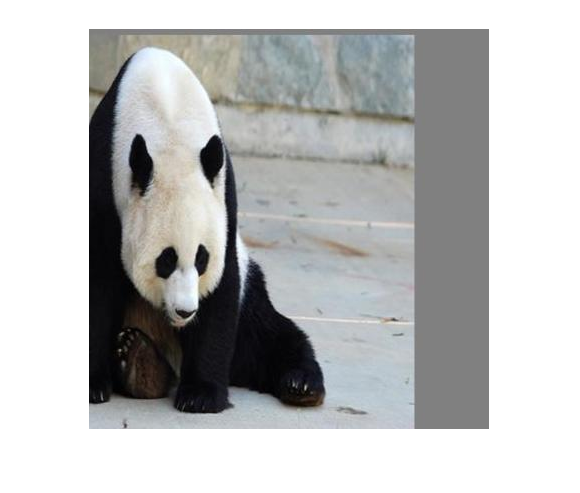

cd D:\Poncelab_Github\as-simple-as-possible

imgdir = ".\data\cloud_vision_demo"

ans = 9×2 table
           labels           scores 
    ____________________    _______

    "Panda"                 0.96679
    "Organism"              0.85866
    "Carnivore"               0.803
    "Terrestrial animal"    0.76562
    "Natural material"       0.7621
    "Fur"                    0.6162
    "Balance"               0.54208
    "Foot"                  0.51668
    "Zoo"                   0.50078


[img2labelmap, imgnms, labels] = parsejson(".\data\cloud_vision_demo\label_result.json");

Let's see some examples images and labels.

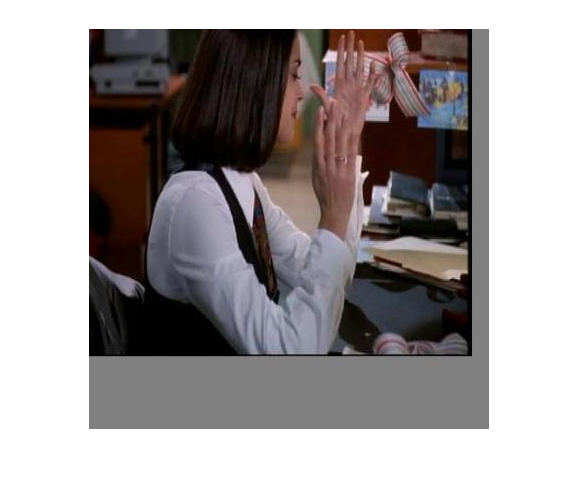

imshow(fullfile(imgdir,"n01494475_17826.JPEG"))

struct2table(img2labelmap("n01494475_17826.JPEG"))

ans = 10×2 table
         labels         scores 
    ________________    _______

    "Hand"              0.95691
    "Eyelash"           0.89415
    "Gesture"            0.8526
    "Event"             0.71184
    "Science"           0.69793
    "Job"               0.63582
    "Home appliance"     0.6342
    "Television"        0.63256
    "Room"              0.60862
    "Sitting"           0.58707



imshow(fullfile(imgdir,"COCO_train2014_000000003008.jpg"))
struct2table(img2labelmap("COCO_train2014_000000003008.jpg"))

Here is the wordcloud of all labels for this batch of images. 

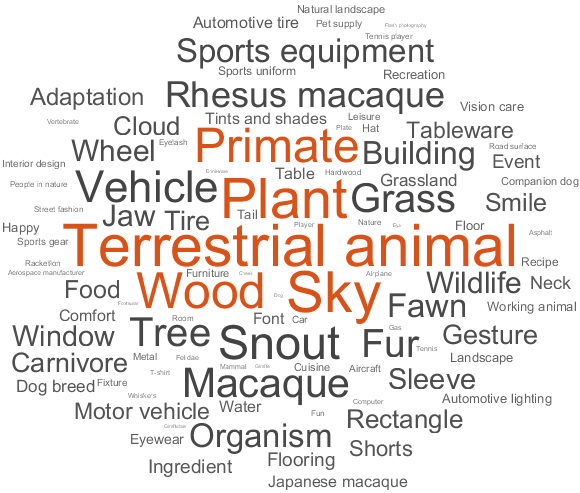

labels_all = cat(1,labels.labels);

wordcloud(categorical(labels_all))

function [img2labelmap, imgnms, labelarr] = parsejson(json_path)
py.importlib.import_module("json");
jsondata = py.json.load(py.open(json_path,"r"));
imgnms = cellfun(@(X)X.string,cell(py.list(jsondata.keys())));
results = cell(py.list(jsondata.values()));

img2labelmap = containers.Map();
labelarr = [];
for i = 1:numel(results)
S = struct();
S.labels = cellfun(@(A)A{1}.string,cell(results{i}))';
S.scores = cellfun(@(A)A{2},cell(results{i}))';
img2labelmap(imgnms(i)) = S;
labelarr = [labelarr;S];
end
% jsonData = jsondecode(fileread(json_path));
return 
end